clear;
load YTest_All.mat;
MethodsNames=["Env-LSTM","TF-LSTM","SS-LSTM","SS-MLR","SS-BP","SS-LSSVM"];
YTest_Pred_All{1}=YTest_Pred_EnvLSTM;
YTest_Pred_All{2}=YTest_Pred_TFLSTM;
YTest_Pred_All{3}=YTest_Pred_sLSTM;
YTest_Pred_All{4}=YTest_Pred_MLR;
YTest_Pred_All{5}=YTest_Pred_BP;
YTest_Pred_All{6}=YTest_Pred_LSSVM;

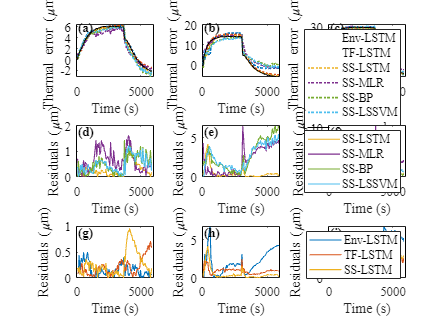

%几种常用的RGB格式的颜色，可选择使用
color=[0,0.447,0.741;
       0.850,0.325,0.098;
       0.929,0.694,0.125;
       0.494,0.184,0.556;
       0.466,0.674,0.188;
       0.301,0.745,0.933;
       0.635,0.078,0.184];
for sub=1:3
    subplot(3,3,sub);
    n=numel(MethodsNames);
    t=60:60:6000;
    for i=1:n
        plot(t,YTest_Pred_All{i}{sub},':','Color',color(i,:),'LineWidth',1.5);
        hold on;
    end
    plot(t,YTest_Measure{sub},'k');
    %ylim([-8,32]);
    xlabel("Time (s)");
    ylabel("Thermal error (\mum)");

    if sub==3
        legend([MethodsNames,"measured"]);
        ylim([-10,32]);
    end
    yyaxis right;
    ylim([0,2]);
    text(100,1.9,"("+ char(96+sub)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    set(gca,'fontsize',12,'fontname','times new roman',"YColor",[0,0,0],"YTick",[]);

    subplot(3,3,sub+3);
    n=numel(MethodsNames);
    t=60:60:6000;
    for i=3:n
        plot(t,abs(YTest_Pred_All{i}{sub}-YTest_Measure{sub}),'-','Color',color(i,:),'LineWidth',1);
        hold on;
    end
    %ylim([0,10]);
    xlabel("Time (s)");
    ylabel("Residuals (\mum)");
    %title("("+ char(96+sub+3)+") Comparison of different methods in Test "+sub);
    if sub==3
        legend(MethodsNames(3:n));
    end
        yyaxis right;
    ylim([0,2]);
    text(100,1.8,"("+ char(96+sub+3)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    set(gca,'fontsize',12,'fontname','times new roman',"YColor",[0,0,0],"YTick",[]);


    subplot(3,3,sub+6);
    n=numel(MethodsNames);
    t=60:60:6000;
    for i=1:3
        plot(t,abs(YTest_Pred_All{i}{sub}-YTest_Measure{sub}),'-','Color',color(i,:),'LineWidth',1);
        hold on;
    end
    %ylim([0,10]);
    xlabel("Time (s)");
    ylabel("Residuals (\mum)");
    %title("("+ char(96+sub+6)+") Comparison of data sources in Test "+sub);
    if sub==3
        legend(MethodsNames(1:3));
    end
    yyaxis right;
    ylim([0,2]);
    text(100,1.8,"("+ char(96+sub+6)+")",'fontsize',12,'fontname','times new roman','FontWeight','bold');
    set(gca,'fontsize',12,'fontname','times new roman',"YColor",[0,0,0],"YTick",[]);
end